# Working with CSV files

Import CSV as matrix. readmatrix auromatically detects the numbers, and leaves out text headers.

readmatrix() imports the data as doubles, and can be directly worked with as vectors.

readtable() imports the data as a table type, so conversion is necessary before working the numbers. The table can be converted to numbers with **table2array().**

### **readmatrix()**

path1 = "C:\Users\Anders Eriksen\Documents\STM32CubeIDE Workspace\N32-HYT271\SHT45-widget\dist\RH_plotter\2025-09-03-1136.csv";
%path2 = "C:\Users\Anders Eriksen\Documents\STM32CubeIDE Workspace\N32-HYT271\SHT45-widget\dist\RH_plotter\2025-09-05-1316.csv";
path2 = "C:\Users\Anders Eriksen\Documents\STM32CubeIDE Workspace\N32-HYT271\SHT45-widget\dist\RH_plotter\2025-09-05-1402.csv";
opts1 = detectImportOptions(path);
opts2 = detectImportOptions(path2);
%source = readmatrix(path, opts);

### readtable()

source1_csv = readtable(path, opts)

source1_csv = 1356×9 table
    Time_s_     RH1      RH2      RH3      RH4      T1       T2       T3       T4  
    _______    _____    _____    _____    _____    _____    _____    _____    _____

     31.93     56.67    52.66    55.55    52.57     24.9    25.04    25.29    24.97
     31.98     56.67    52.86    55.55    52.57     24.9    24.92    25.29    24.97
     32.04     56.67    52.86    56.09    52.57     24.9    24.92    25.06    24.97
     32.09     56.67    52.86    56.09       53     24.9    24.92    25.06    24.86
     32.97     56.68    52.86    56.09       53     24.9    24.92    25.06    24.86
     33.03     56.68    52.89    56.09       53     24.9    24.93    25.06    

source2_csv = readtable(path2, opts2)

source2_csv = 3528×9 table
    Time_s_     RH1      RH2      RH3      RH4      T1       T2       T3       T4  
    _______    _____    _____    _____    _____    _____    _____    _____    _____

      9.03     58.99    57.58    59.04     57.4    24.52    24.61    24.77    24.43
      9.08     58.99    57.53    59.04     57.4    24.52     24.6    24.77    24.43
      9.26     58.99    57.53    59.08     57.4    24.52     24.6    24.77    24.43
      9.36     58.99    57.53    59.08    57.44    24.52     24.6    24.77    24.43
      9.79        59    57.53    59.08    57.44    24.51     24.6    24.77    24.43
      9.85        59    57.57    59.08    57.44    24.51    24.61    24.77    

data1 = table2array(source_csv);
data2 = table2array(source2_csv);
data_header = string(opts.VariableNames);

### Plot data

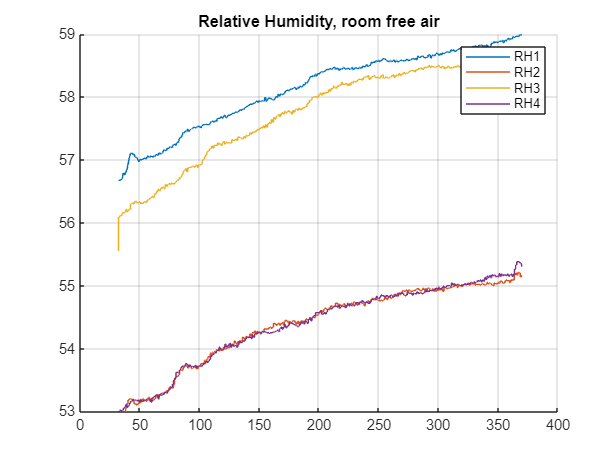

fig_num = 0;

fig_num = fig_num + 1;
fig = figure(fig_num);
clf(fig)
hold on
grid on
title('Relative Humidity, room free air')
for i = 2:5
    plot(data1(:, 1),data1(:, i))
    ylim([53, 59])
end
legend(data_header(2:5))

hold off

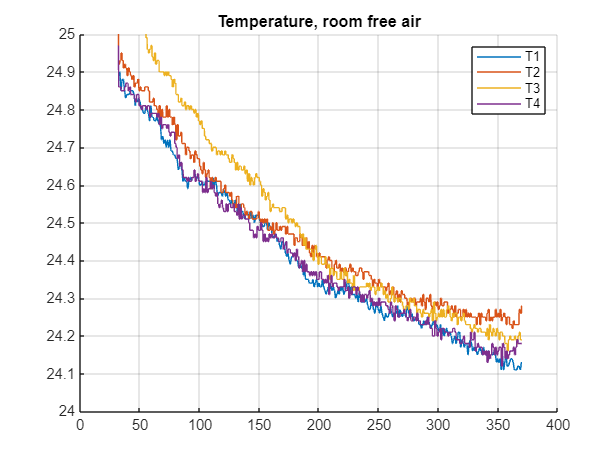

fig_num = fig_num + 1;
fig = figure(fig_num);
clf(fig);
hold on
grid on
title('Temperature, room free air')
for i = 6:9
    plot(data1(:, 1), data1(:, i))
    ylim([24, 25])
end
legend(data_header(6:9))
hold off

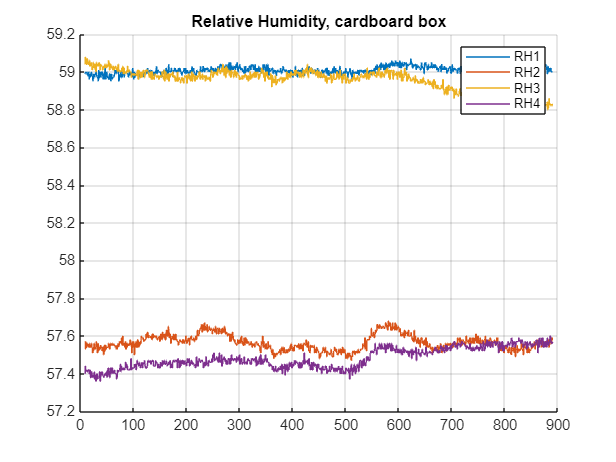

start = 1 * 2;

fig_num = fig_num + 1;
fig = figure(fig_num);
clf(fig)
hold on
grid on
title('Relative Humidity, cardboard box')
for i = 2:5
    plot(data2(start:end, 1),data2(start:end, i))
    %ylim([56, 60])
end
legend(data_header(2:5))

hold off

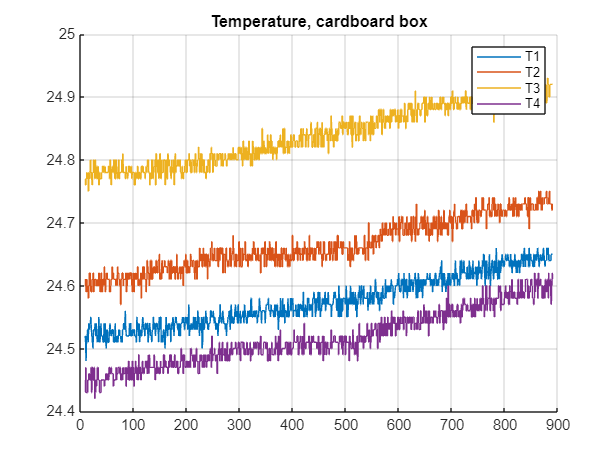

fig_num = fig_num + 1;
fig = figure(fig_num);
clf(fig);
hold on
grid on
title('Temperature, cardboard box')
for i = 6:9
    plot(data2(start:end, 1), data2(start:end, i))
    %ylim([24.2, 25.3])
end
legend(data_header(6:9))
hold off